nPoints = 200;

% Pure lateral test case
Fz      = ones(nPoints,1).*1500;            % vertical load         (N)
kappa	= linspace(-0.2, 0.2, nPoints)';               % longitudinal slip 	(-) (-1 = locked wheel)
alpha	= ones(nPoints,1).*deg2rad(0);     % side slip angle    	(radians)
gamma	= ones(nPoints,1).*deg2rad(0);               % inclination angle 	(radians)
phit 	= ones(nPoints,1).*0;               % turnslip            	(1/m)
Vx   	= ones(nPoints,1).*100;              % forward velocity   	(m/s)
P       = ones(nPoints,1).*0.8*10^5;

% Create a string with the name of the TIR file
TIRfile = './doc/examples/fsae/fsaettc_obfuscated.tir';

% Select a Use Mode
useMode = 122;

% Wrap all inputs in one matrix
inputs = [Fz kappa alpha gamma phit Vx P];

% Store the output from mfeval in a 2D Matrix
output = mfeval(TIRfile, inputs, useMode);

tyre = mftyre.v62.Model(TIRfile);
FX2 = tyre.eval(alpha, kappa, gamma, P, Fz, 0);

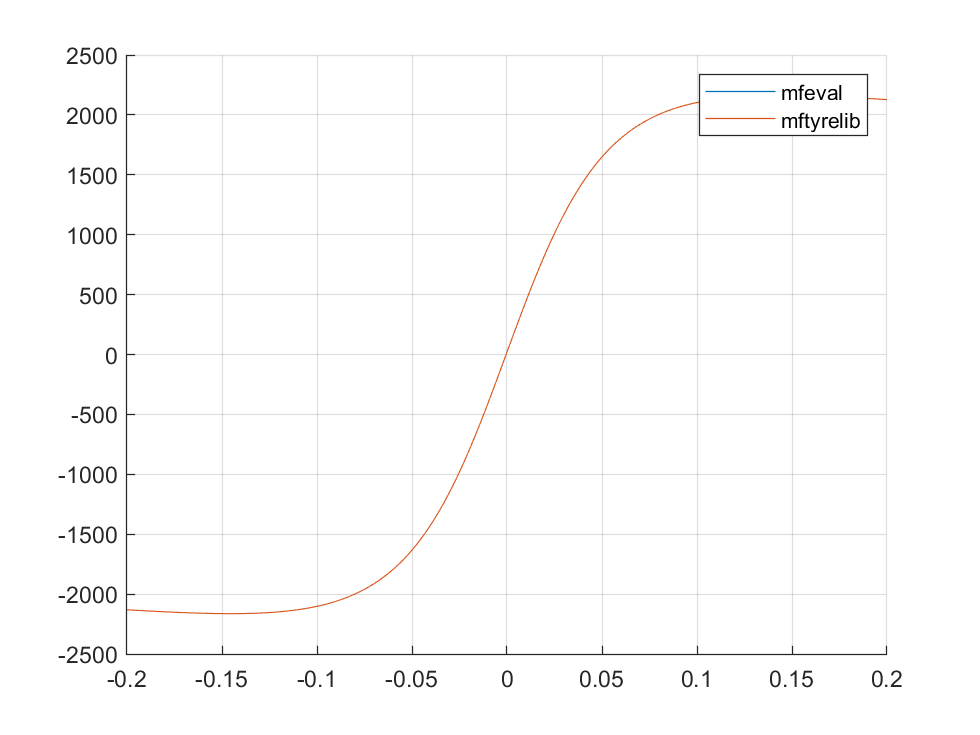

FX = output(:,1);
figure
grid on; hold on
plot(kappa, FX)
plot(kappa, FX2)
legend mfeval mftyrelib